clear;
clc;

file_paths = {'location(5,3)responder1.txt', 'location(5,3)responder2.txt', 'location(5,3)responder3.txt', 'location(5,3)responder4new.txt', 'location(5,3)responder5.txt'};
test_file_paths = {'location(6,2)responder1.txt', 'location(6,2)responder2.txt', 'location(6,2)responder3.txt', 'location(6,2)responder4.txt', 'location(6,2)responder5.txt'};

all_CIR_real_all = {};
all_CIR_imag_all = {};

% Boucle pour lire les valeurs CIR de chaque fichier d'entraînement
for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

Total number of read CIR pairs for location(5,3)responder1.txt: 984
Total number of read CIR pairs for location(5,3)responder2.txt: 1034
Total number of read CIR pairs for location(5,3)responder3.txt: 1028
Total number of read CIR pairs for location(5,3)responder4new.txt: 1006
Total number of read CIR pairs for location(5,3)responder5.txt: 1032


disp(['==========================================================================']);         

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.42681 |      86.769 |     0.42681 |     0.42681 |       200.07 |    0.0031267 |        false |
|    2 | Best   |     0.20315 |      0.4299 |     0.20315 |     0.21821 |       889.66 |       18.842 |        false |
|    3 | Accept |     0.20315 |     0.65057 |     0.20315 |     0.20359 |       815.69 |       1.8043 |         true |
|    4 | Accept |     0.20315 |     0.37393 |     0.20315 |     0.20315 |    0.0078838 |      0.11717 |         true |
|    5 | Accept |     0.20315 |     0.33579 |   

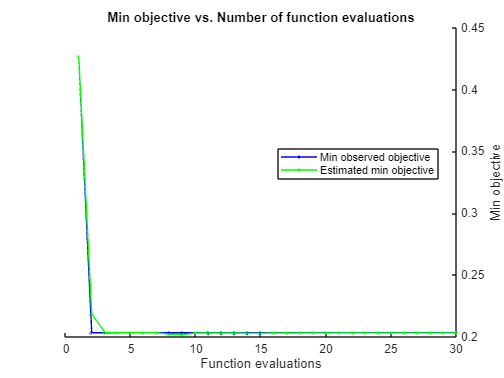


% Initialiser les vecteurs pour les caractéristiques et les étiquettes d'entraînement
features = [];
labels = [];

% Boucle pour générer les caractéristiques pour chaque fichier d'entraînement
for i = 1:length(file_paths)
    file_path = file_paths{i};
    CIR_real_all = all_CIR_real_all{i};
    CIR_imag_all = all_CIR_imag_all{i};

    for CIRNumber = 1:length(CIR_real_all)
        % Extraire les valeurs réelles et imaginaires
        CIR_real = CIR_real_all{CIRNumber}(735:820)';
        CIR_imag = CIR_imag_all{CIRNumber}(735:820)';
        
        % Calculer les valeurs complexes et leurs métriques
        CIR_complex_values = CIR_real + 1i * CIR_imag;
        CIR_phase = angle(CIR_complex_values);

        % Calculer les caractéristiques
        varPhase_value = var(CIR_phase);
        stdPhase_value = std(CIR_phase);
        ratio_negative_phases = sum(CIR_phase < 0) / length(CIR_phase);

        % Ajouter les caractéristiques à l'ensemble de données
        features = [features; varPhase_value, stdPhase_value, ratio_negative_phases];

        % Ajouter les étiquettes (0 pour LOS, 1 pour NLOS)
        if strcmp(file_path, 'location(5,3)responder5.txt')
            labels = [labels; 1]; % NLOS
        else
            labels = [labels; 0]; % LOS
        end
    end
end

% Séparer les données en ensemble d'entraînement et de test
cv = cvpartition(labels, 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

% Entraîner le modèle sur l'ensemble d'entraînement
svmModel = fitcsvm(features(trainIdx, :), labels(trainIdx), 'OptimizeHyperparameters', 'auto');


% Prédiction sur l'ensemble de test interne
predictions_internal = predict(svmModel, features(testIdx, :));

% Évaluation des performances sur l'ensemble de test interne
accuracy_internal = sum(predictions_internal == labels(testIdx)) / length(labels(testIdx));
disp(['Internal Test Set Accuracy: ', num2str(accuracy_internal)]);

Internal Test Set Accuracy: 0.79738



% Matrice de confusion pour l'ensemble de test interne
confMat_internal = confusionmat(labels(testIdx), predictions_internal);
disp('Internal Confusion Matrix:');

Internal Confusion Matrix:


disp(confMat_internal);

        1216           0
         309           0




% Initialiser les vecteurs pour les caractéristiques et les étiquettes de test
test_features = [];
test_labels = [];

% Boucle pour générer les caractéristiques pour chaque fichier de test
for i = 1:length(test_file_paths)
    file_path = test_file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);

    for CIRNumber = 1:length(CIR_real_all)
        % Extraire les valeurs réelles et imaginaires
        CIR_real = CIR_real_all{CIRNumber}(735:820)';
        CIR_imag = CIR_imag_all{CIRNumber}(735:820)';
        
        % Calculer les valeurs complexes et leurs métriques
        CIR_complex_values = CIR_real + 1i * CIR_imag;
        CIR_phase = angle(CIR_complex_values);

        % Calculer les caractéristiques
        varPhase_value = var(CIR_phase);
        stdPhase_value = std(CIR_phase);
        ratio_negative_phases = sum(CIR_phase < 0) / length(CIR_phase);

        % Ajouter les caractéristiques à l'ensemble de données de test
        test_features = [test_features; varPhase_value, stdPhase_value, ratio_negative_phases];

        % Ajouter les étiquettes (0 pour LOS, 1 pour NLOS)
        if strcmp(file_path, 'location(6,2)responder5.txt')
            test_labels = [test_labels; 1]; % NLOS
        else
            test_labels = [test_labels; 0]; % LOS
        end
    end
end

% Prédiction sur l'ensemble de test externe
predictions_external = predict(svmModel, test_features);

% Évaluation des performances sur l'ensemble de test externe
accuracy_external = sum(predictions_external == test_labels) / length(test_labels);
disp(['External Test Set Accuracy: ', num2str(accuracy_external)]);

External Test Set Accuracy: 0.79973



% Matrice de confusion pour l'ensemble de test externe
confMat_external = confusionmat(test_labels, predictions_external);
disp('External Confusion Matrix:');

External Confusion Matrix:


disp(confMat_external);

        4121           0
        1032           0

